## Initialization and Setup

clear             % clear variables from Workspace
addpath('Final')  % Include the Final folder in the path

## Import raw data

Read data from Excel

FlightData = importFlightData('FlightData.xlsx');
FlightData = FlightData(FlightData.TrueAirSpeed >= 10,:)

FlightData = 42584x13 table
    FuelQuantity    OilPressure    OilTemperature    LatitudePosition    LongitudePosition    Altitude    ExhaustTemperature    FuelFlow    FanSpeed    TrueAirSpeed    WindDirection    WindSpeed    WeightOnWheels
    ____________    ___________    ______________    ________________    _________________    ________    __________________    ________    ________    ____________    _____________    _________    ______________

       7966.8         90.354           58.805             44.891              -63.508           204    

## Visualize Data

geoplot(FlightData.LatitudePosition,FlightData.LongitudePosition)
title("LongitudePosition vs LatitudePosition")
legend("show")

## Clean Outlier Data

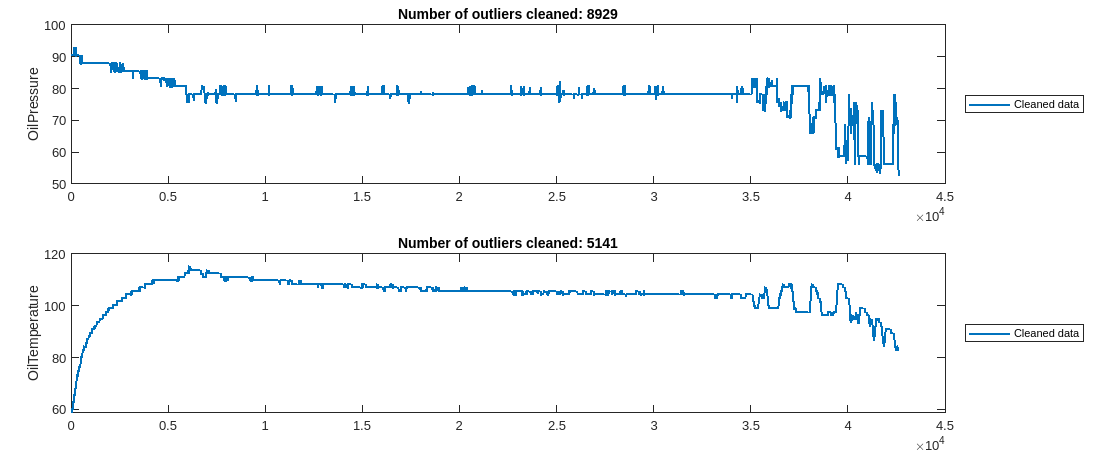

% Fill outliers
[cleanedData,outlierIndices2] = filloutliers(FlightData,"linear","movmedian",100, ...
    "DataVariables",["OilPressure","OilTemperature"]);

% Display results
f = figure("Units","Normalized");
dv = [2 3];
N = numel(dv);
f.Position = [0 0 1 N/3];
tiledlayout(N,1,"Padding","compact");
for k = 1:N
    nexttile
    plot(cleanedData.(dv(k)),"SeriesIndex",1,"LineWidth",1.5, ...
        "DisplayName","Cleaned data")

    title("Number of outliers cleaned: " + nnz(outlierIndices2(:,dv(k))))
    legend("Location","EastOutside")
    ylabel(FlightData.Properties.VariableNames{dv(k)},"Interpreter","none")
end

f.NextPlot = "new";
clear f dv N k